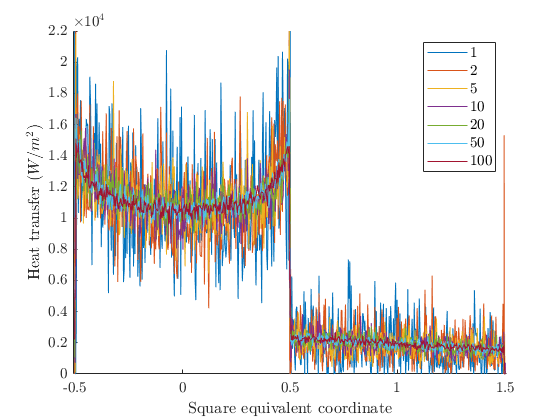

clear

D1 = readmatrix('./fnum_convergence/surf1.txt');
D1 = sortrows(D1(8:1279,1:10),1);
D1 = D1(1:651,:);

D2 = readmatrix('./fnum_convergence/surf2.txt');
D2 = sortrows(D2(8:1279,1:10),1);
D2 = D2(1:651,:);

D5 = readmatrix('./fnum_convergence/surf5.txt');
D5 = sortrows(D5(8:1279,1:10),1);
D5 = D5(1:651,:);

D10 = readmatrix('./fnum_convergence/surf10.txt');
D10 = sortrows(D10(8:1279,1:10),1);
D10 = D10(1:651,:);

D20 = readmatrix('./fnum_convergence/surf20.txt');
D20 = sortrows(D20(8:1279,1:10),1);
D20 = D20(1:651,:);

D50 = readmatrix('./fnum_convergence/surf50.txt');
D50 = sortrows(D50(8:1279,1:10),1);
D50 = D50(1:651,:);

D100 = readmatrix('./fnum_convergence/surf100.txt');
D100 = sortrows(D100(8:1279,1:10),1);
D100 = D100(1:651,:);

coords=coords('./fnum_convergence/squareroundhp2.txt');
coords=coords(1:651,:);

fig1=figure;
hold on
plot(coords(:,2),D1(:,10))
plot(coords(:,2),D2(:,10))
plot(coords(:,2),D5(:,10))
plot(coords(:,2),D10(:,10))
plot(coords(:,2),D20(:,10))
plot(coords(:,2),D50(:,10))
plot(coords(:,2),D100(:,10))
legend('1','2','5','10','20','50','100','interpreter','latex','FontSize',11)
xlabel('Square equivalent coordinate','interpreter','latex','FontSize',11)
ylabel('Heat transfer ($W / m^2$)','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
xlim([-0.51, 1.51])
ylim([0,2.2e4])
exportgraphics(fig1,'../Images/3. Methodology/Fnum convergence/fnumconv.pdf','ContentType','vector');